# Netflix originals data analysis

This is my data analysis. 

I could explan here where I got the data from, what we intend to do, whatever story I want to tell.

% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 6);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Title", "Genre", "Premiere", "Runtime", "IMDBScore", "Language"];
opts.VariableTypes = ["string", "categorical", "datetime", "double", "double", "categorical"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Title", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["Title", "Genre", "Language"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Premiere", "InputFormat", "MMMM d, yyyy");

% Import the data
NetflixOriginals = readtable("/Users/mcrouche/MATLAB-Drive/Repositories/netflixAnalysis/NetflixOriginals.csv", opts);

% Clear temporary variables
clear opts

% Display results
NetflixOriginals

NetflixOriginals = 584×6 table
                  Title                           Genre              Premiere      Runtime    IMDBScore        Language    
    _________________________________    _______________________    ___________    _______    _________    ________________

    "Enter the Anime"                    Documentary                05-Aug-2019       58         2.5       English/Japanese
    "Dark Forces"                        Thriller                   21-Aug-2020       81         2.6       Spanish         
    "The App"                            Science fiction/Drama      26-Dec-2019       79         2.6       Italian         
    "The Open House"                     Horror thriller            19-Jan-2018       94         3.2       English         
    "Kaali Khuhi"   

height(NetflixOriginals)

ans = 584

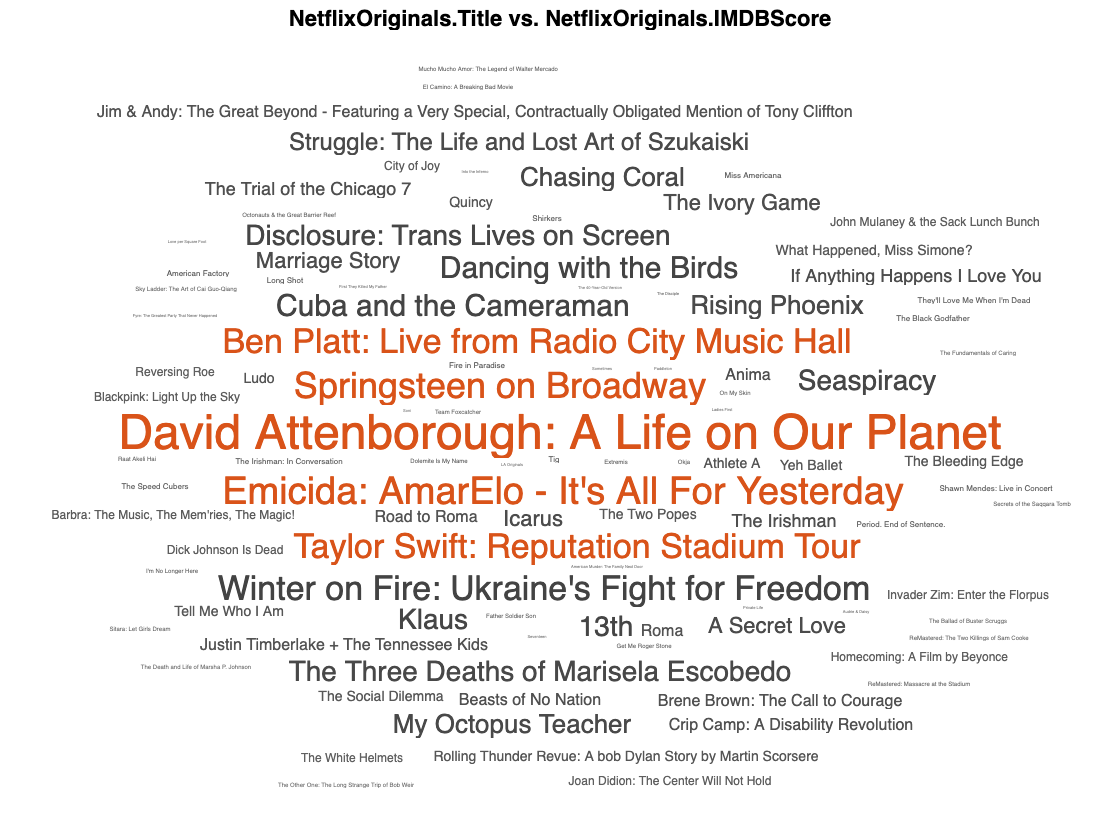

% Create wordcloud of NetflixOriginals.Title and NetflixOriginals.IMDBScore
wc = wordcloud(NetflixOriginals.Title,NetflixOriginals.IMDBScore);

% Add title
title("NetflixOriginals.Title vs. NetflixOriginals.IMDBScore")

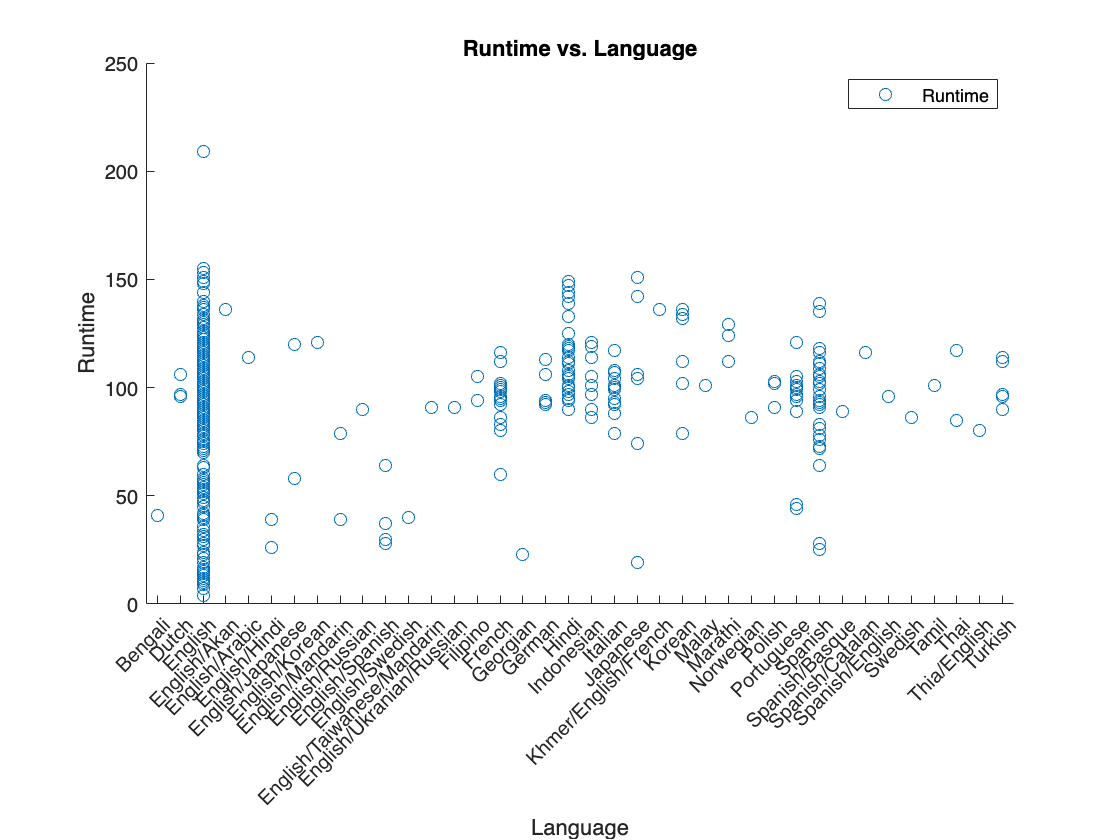

% Create scatter of NetflixOriginals.Language and NetflixOriginals.Runtime
s = scatter(NetflixOriginals,"Language","Runtime","DisplayName","Runtime");

% Add xlabel, ylabel, title, and legend
xlabel("Language")
ylabel("Runtime")
title("Runtime vs. Language")
legend

# Italian language movies

Tell more of the story of what I am doing

- step 1

- step 2

italianTable = NetflixOriginals(NetflixOriginals.Language == "Italian", :)

italianTable = 14×6 table
                Title                        Genre              Premiere      Runtime    IMDBScore    Language
    _____________________________    ______________________    ___________    _______    _________    ________

    "The App"                        Science fiction/Drama     26-Dec-2019       79         2.6       Italian 
    "5 Star Christmas"               Comedy                    07-Dec-2018       95         4.6       Italian 
    "The Players"                    Comedy                    15-Jul-2020       88         4.6       Italian 
    "The Binding"                    Drama                     02-Oct-2020       93         4.7       Italian 
    "The Beast"                      Drama                     27-Nov-2020       99         5.2       I

worstItalianMovie = italianTable(italianTable.IMDBScore==min(italianTable.IMDBScore),:)

worstItalianMovie = 1×6 table
      Title              Genre             Premiere      Runtime    IMDBScore    Language
    _________    _____________________    ___________    _______    _________    ________

    "The App"    Science fiction/Drama    26-Dec-2019      79          2.6       Italian 


max(italianTable.IMDBScore)

ans = 7.3000

bestItalianMovie = italianTable(italianTable.IMDBScore==max(italianTable.IMDBScore),:)

bestItalianMovie = 1×6 table
       Title           Genre        Premiere      Runtime    IMDBScore    Language
    ____________    ___________    ___________    _______    _________    ________

    "On My Skin"    Crime drama    12-Sep-2018      100         7.3       Italian 


# Suggested exercises

-  Repeat the Italian study but for Spanish?

-  Create a histogram of Premiere dates for the whole data set?

- Create a histogram of Premiere dates for the movies in French?

- What are the top 5 movie genres? (Hint: Use the 'Compute by Group' Task to get the number of movies in each Genre and then sort the results)

- Create a word cloud of movie genres where the size of each genre is proportional to its popularity.